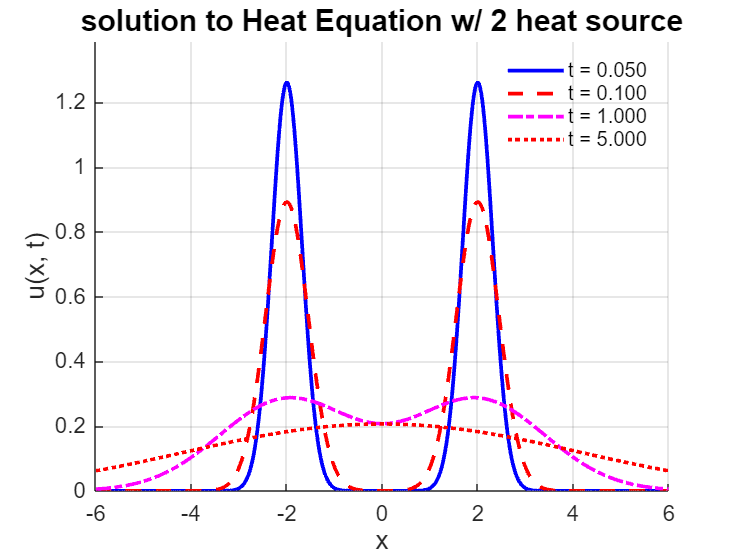

% MATLAB Code to Plot the Solution u(x,t) for the Heat Equation with Two Dirac Delta Initial Conditions
% Parameters: kappa = 1, a = 1, x0 = 2
% Time Instances: t = 0.001, t = 0.1, t = 1, t = 10

% Clear workspace and command window
clear; clc;

% --- Parameters ---
kappa = 1;     % Diffusion coefficient
a = 1;         % Amplitude of delta functions
x0 = 2;        % Location of delta functions

% --- Spatial Domain ---
x_min = -6;             % Minimum x-value
x_max = 6;              % Maximum x-value
num_points = 1000;      % Number of spatial points for smooth plots
x = linspace(x_min, x_max, num_points);  % Spatial grid

% --- Time Instances ---
t_values = [0.05, 0.1, 1, 5];  % Specified times to plot u(x,t)

% --- Initialize Figure ---
figure;
hold on;  % Allow multiple plots on the same figure
grid on;  % Enable grid
set(gca, 'FontSize', 12);  % Increase axis font size for readability

% --- Plot u(x, t) for Each Time Instance ---
colors = {'b', 'r', 'm', 'r'};       % Define distinct colors for each time
line_styles = {'-', '--', '-.', ':'};  % Define distinct line styles for each time

for idx = 1:length(t_values)
    t = t_values(idx);
    
    % Compute Phi(x + x0, t) and Phi(x - x0, t) if t > 0
    Phi_plus = (1 / sqrt(4 * pi * kappa * t)) * exp(-((x + x0).^2) / (4 * kappa * t));
    Phi_minus = (1 / sqrt(4 * pi * kappa * t)) * exp(-((x - x0).^2) / (4 * kappa * t));
    
    % Compute the solution u(x,t)
    u = a * (Phi_plus + Phi_minus);
    
    % Plot u(x,t) with distinct colors and line styles
    plot(x, u, 'Color', colors{idx}, 'LineStyle', line_styles{idx}, ...
        'LineWidth', 2, 'DisplayName', sprintf('t = %.3f', t));
end

% --- Labels and Title ---
xlabel('x', 'FontSize', 14);
ylabel('u(x, t)', 'FontSize', 14);
title('solution to Heat Equation w/ 2 heat source', 'FontSize', 16);

% --- Legend ---
legend('Location', 'northeast');
legend('boxoff');  % Remove the legend box for aesthetics

% --- Adjust Axes Limits ---
% Determine the maximum u value across all plots for y-axis scaling
all_u = [];
for t = t_values
    Phi_plus = (1 / sqrt(4 * pi * kappa * t)) * exp(-((x + x0).^2) / (4 * kappa * t));
    Phi_minus = (1 / sqrt(4 * pi * kappa * t)) * exp(-((x - x0).^2) / (4 * kappa * t));
    all_u = [all_u, a * (Phi_plus + Phi_minus)];
end
max_u = max(all_u);
ylim([0, max_u * 1.1]);  % Add 10% padding to the y-axis

% --- Enhance Plot Appearance ---
set(gcf, 'Position', [100, 100, 800, 600]);  % Set figure size for better visibility

% --- Hold Off ---
hold off;

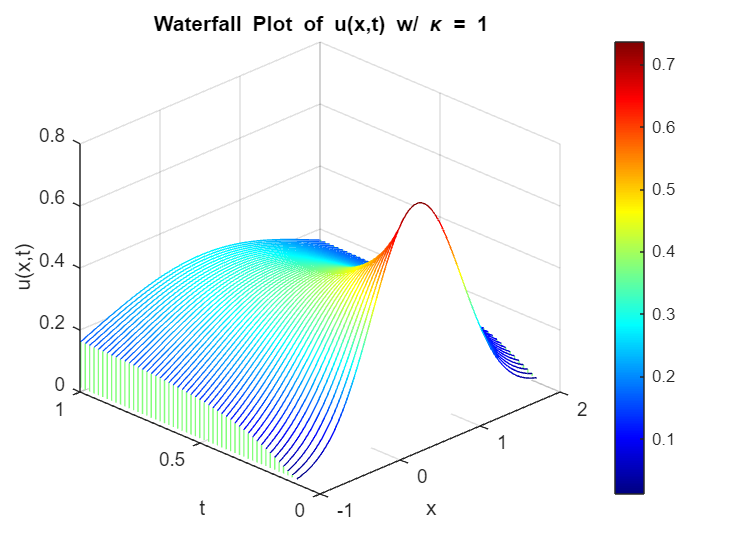

% MATLAB Script to Plot u(x, t) as a Waterfall Plot

% Clear workspace and command window for a fresh start
clear;
clc;

% Define the thermal diffusivity constant
k = 1;

% Define the range for x and t
x_min = -1;   % Minimum x value
x_max = 2;    % Maximum x value
t_min = 0.1;  % Minimum t value (avoids t = 0 to prevent division by zero)
t_max = 1;    % Maximum t value

% Number of points in x and t for smoothness
num_x = 100;  % Number of points along x-axis
num_t = 50;   % Number of points along t-axis

% Create linearly spaced vectors for x and t
x = linspace(x_min, x_max, num_x);
t = linspace(t_min, t_max, num_t);

% Create a meshgrid for x and t
[X, T] = meshgrid(x, t);

% Compute the denominator sqrt(4kt)
denominator = sqrt(4 * k * T);

% Compute u(x, t) using the given formula
% Ensure element-wise division by using ./
% MATLAB's erf function operates element-wise
U = 0.5 * (erf(X ./ denominator) - erf((X - 1) ./ denominator));

% Create the waterfall plot
figure;
waterfall(X, T, U);

% Enhance the plot with labels and title
xlabel('x');
ylabel('t');
zlabel('u(x,t)');
title('Waterfall Plot of u(x,t) w/ \kappa = 1');
grid on;
colormap jet; % Optional: Change color map for better visualization

% Adjust viewing angle for better perspective (optional)
view(-45, 30); % [azimuth, elevation]

% Add a colorbar to indicate the magnitude of u(x,t) (optional)
colorbar;